dataset.images

ans =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    0.0078    0.0157    0.0157    0.0157    0.0157    0.0157         0         0   

dataset.key

ans = 'ABCDEFGHIJKLMNOPQRSTUVWXYZ'

dataset.labels

ans =      9
     1
    16
    15
    23
     1
    16
     5
     6
     2


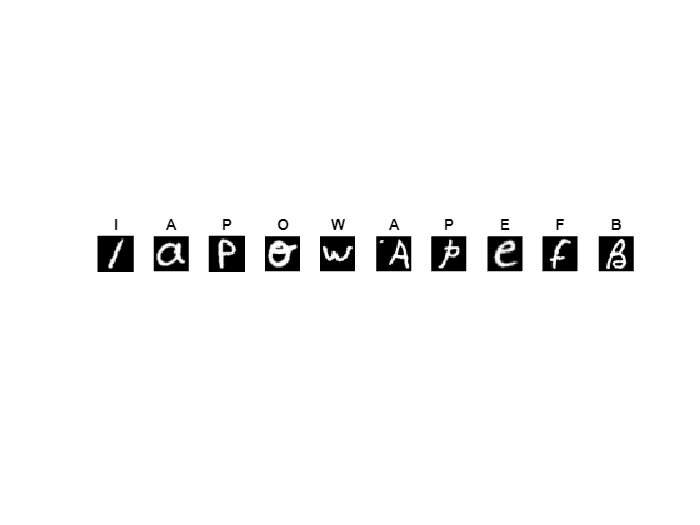

for i = 1:10
    % Reshape the image from 1x784 to 28x28
    img = reshape(dataset.images(i, :), [28, 28]);

    % Display the image in a subplot
    subplot(1, 10, i);
    imshow(img, []);
    title(dataset.key(dataset.labels(i)));
end

%Prepare the data
[trainData, valData, testData] = splitDataset(dataset, 0.62, 0.22);
% Convert images to [28 28 1 size(dataset.images, 1)] format
trainImages = reshape(trainData.images', [28, 28, 1, size(trainData.images, 1)]);
valImages = reshape(valData.images', [28, 28, 1, size(valData.images, 1)]);
testImages = reshape(testData.images', [28, 28, 1, size(testData.images, 1)]);

% Convert labels to categorical format
trainLabels = categorical(trainData.labels);
valLabels = categorical(valData.labels);
testLabels = categorical(testData.labels);
% Fit the k-NN model
tic; % Start timing
knnModel = fitcknn(trainData.images, trainLabels, 'Distance', 'euclidean'); % Or 'cosine', etc.
knnTrainingTime = toc; % Stop timing

% Predict using the k-NN model
tic; % Start timing
knnPredictions = predict(knnModel, testData.images);
knnTestingTime = toc; % Stop timing

% Calculate accuracy
knnAccuracy = sum(knnPredictions == testLabels) / numel(testLabels);

% Display results
fprintf('k-NN Accuracy: %.2f%%\n', knnAccuracy * 100);

k-NN Accuracy: 78.39%


fprintf('Training Time: %.2fs\n', knnTrainingTime);

Training Time: 0.11s


fprintf('Testing Time: %.2fs\n', knnTestingTime);

Testing Time: 5.28s


% Reshape data for manual k-NN
trainImagesFlat = double(reshape(trainImages, 28*28, []));
testImagesFlat = double(reshape(testImages, 28*28, []));
k = 26; % For example, using 5 nearest neighbours

% L2 Distance
tic;
predictionsL2 = knn_L2(trainImagesFlat, double(trainLabels), testImagesFlat, k);
knnL2Time = toc;

% L1 Distance
tic;
predictionsL1 = knn_L1(trainImagesFlat, double(trainLabels), testImagesFlat, k);
knnL1Time = toc;

% Convert predictions to categorical
predictionsL2 = categorical(predictionsL2);
predictionsL1 = categorical(predictionsL1);

% Calculate accuracy
accuracyL2 = sum(predictionsL2 == testLabels) / numel(testLabels);
accuracyL1 = sum(predictionsL1 == testLabels) / numel(testLabels);

fprintf('k-NN L2 Accuracy: %.2f%%\n', accuracyL2 * 100);

k-NN L2 Accuracy: 73.85%


fprintf('k-NN L2 Computation Time: %.2fs\n', knnL2Time);

k-NN L2 Computation Time: 80.00s


fprintf('k-NN L1 Accuracy: %.2f%%\n', accuracyL1 * 100);

k-NN L1 Accuracy: 71.78%


fprintf('k-NN L1 Computation Time: %.2fs\n', knnL1Time);

k-NN L1 Computation Time: 79.32s


Training on single GPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:01 |        3.71% |        3.90% |       3.2993 |       3.2597 |          0.0600 |
|       4 |          50 |       00:00:04 |       45.90% |       53.60% |       1.8477 |       2.5128 |          0.0600 |
|       7 |         100 |       00:00:07 |       68.16% |       76.05% |       0.9982 |       1.8342 |          0.0600 |
|      10 |         150 |       00:00:11 |       75.10% |       81.91% |       0.8118 |   

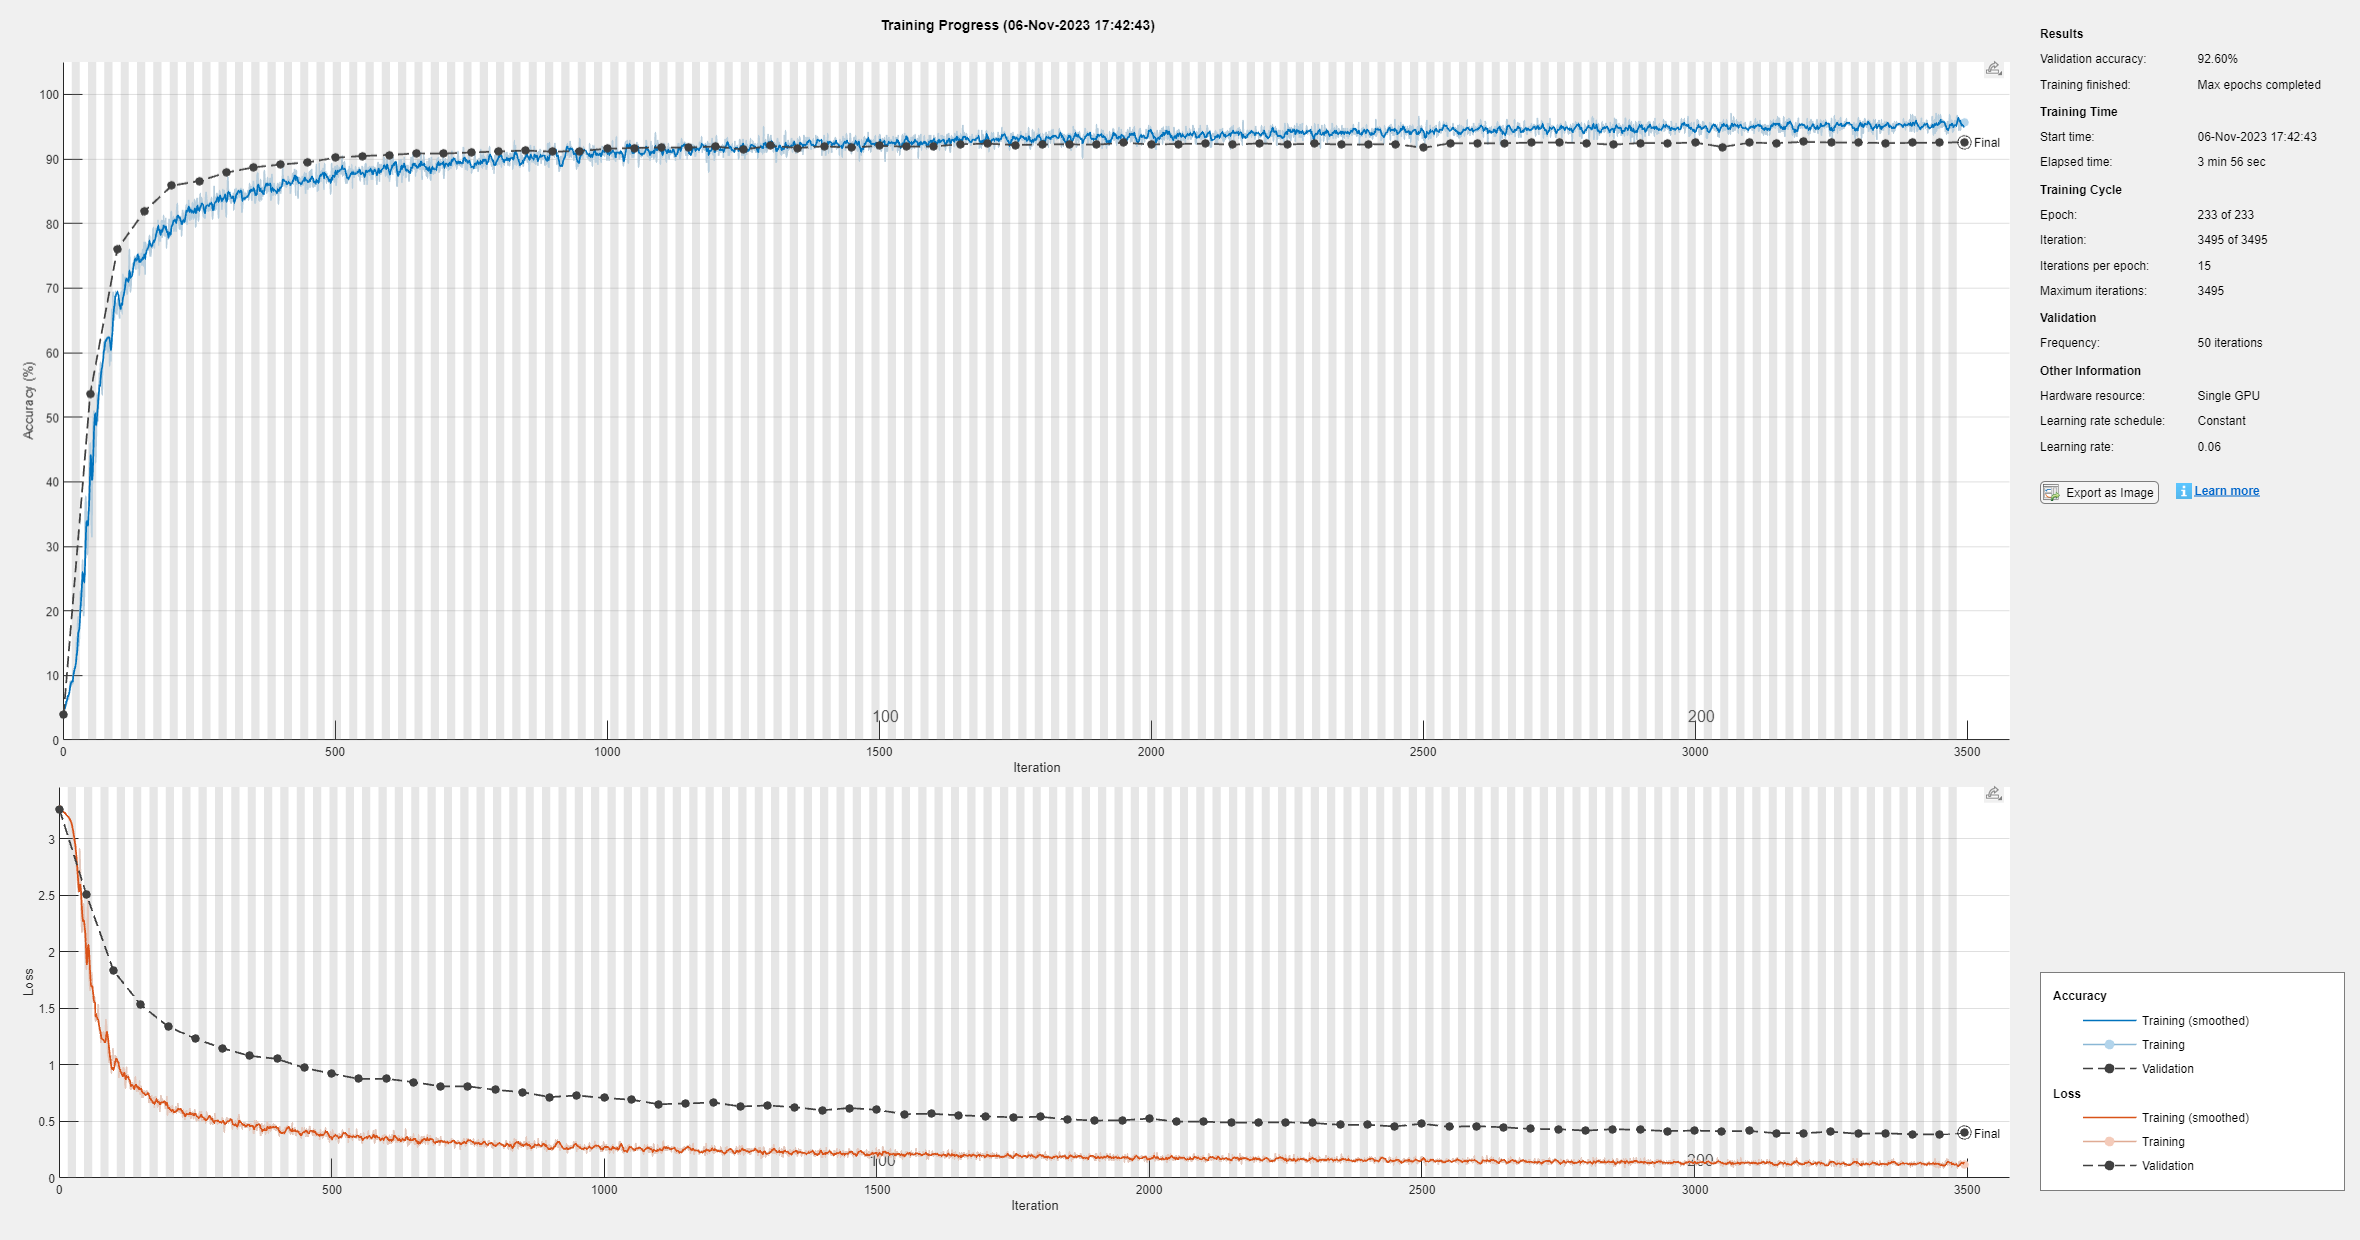


% Define the augmentation operations
imageAugmenter = imageDataAugmenter( ...
    'RandXReflection', false, ... % Horizontal reflection
    'RandRotation', [-10,10], ... % Random rotation in the range [-10, 10] degrees
    'RandXTranslation', [-2 2], ... % Random horizontal shift
    'RandYTranslation', [-2 2], ... % Random vertical shift
    'RandScale', [0.9 1.1]); % Random scaling

augmentedTrainImages = augmentedImageDatastore([28 28 1], trainImages, trainLabels, ...
    'DataAugmentation', imageAugmenter);
%init layers
layers = [
    imageInputLayer([28 28 1], 'Name', 'input')
    
    convolution2dLayer(2, 64, 'Padding', 'same', 'Name', 'conv_1')
    reluLayer('Name', 'relu_1')
    dropoutLayer(0.5, 'Name', 'dropout1')
    maxPooling2dLayer(2, 'Stride', 2, 'Name', 'maxpool_1')
    
    convolution2dLayer(7, 32, 'Padding', 'same', 'Name', 'conv_2')
    swishLayer('Name', 'swish_2')
    dropoutLayer(0.5, 'Name', 'dropout2')
    maxPooling2dLayer(4, 'Stride', 2, 'Name', 'maxpool_2')
    
    fullyConnectedLayer(512, 'Name', 'fc_1')
    reluLayer('Name', 'relu_3')
    dropoutLayer(0.4, 'Name', 'dropout3')
    
    fullyConnectedLayer(26, 'Name', 'fc_2')
    softmaxLayer('Name', 'softmax')
    classificationLayer('Name', 'classification')
];

GPTdesignedlayers = [
    imageInputLayer([28 28 1], 'Name', 'input')
    
    convolution2dLayer(3, 32, 'Padding', 'same', 'Name', 'conv_1')
    batchNormalizationLayer('Name', 'bn_1')
    reluLayer('Name', 'relu_1')
    maxPooling2dLayer(2, 'Stride', 2, 'Name', 'maxpool_1')
    
    convolution2dLayer(3, 64, 'Padding', 'same', 'Name', 'conv_2')
    batchNormalizationLayer('Name', 'bn_2')
    swishLayer('Name', 'swish_2')
    maxPooling2dLayer(2, 'Stride', 2, 'Name', 'maxpool_2')
    
    convolution2dLayer(3, 128, 'Padding', 'same', 'Name', 'conv_3')
    batchNormalizationLayer('Name', 'bn_3')
    reluLayer('Name', 'relu_3')
    maxPooling2dLayer(2, 'Stride', 2, 'Name', 'maxpool_3')
    
    fullyConnectedLayer(1024, 'Name', 'fc_1')
    reluLayer('Name', 'relu_4')
    dropoutLayer(0.4, 'Name', 'dropout4')
    
    fullyConnectedLayer(256, 'Name', 'fc_2')
    reluLayer('Name', 'relu_5')
    dropoutLayer(0.3, 'Name', 'dropout5')
    
    fullyConnectedLayer(26, 'Name', 'fc_3')
    softmaxLayer('Name', 'softmax')
    classificationLayer('Name', 'classification')
];

options = trainingOptions('sgdm', ...
    'MaxEpochs', 233, ...
    'MiniBatchSize', 1024, ...
    'InitialLearnRate', 6e-2, ...
    'Momentum', 0.06, ...
    'Shuffle', 'every-epoch', ...
    'ValidationData', {valImages, valLabels}, ...
    'Verbose', true, ...
    'Plots', 'training-progress');
net = trainNetwork(trainImages, trainLabels, layers, options);

Training on single GPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:01 |        3.03% |        7.03% |       4.8170 |       3.3207 |          0.0300 |
|       4 |          50 |       00:00:04 |       56.05% |       73.99% |       1.4322 |       1.0151 |          0.0300 |
|       7 |         100 |       00:00:08 |       69.63% |       81.99% |       0.9528 |       0.6290 |          0.0300 |
|      10 |         150 |       00:00:11 |       77.54% |       84.97% |       0.7310 |   

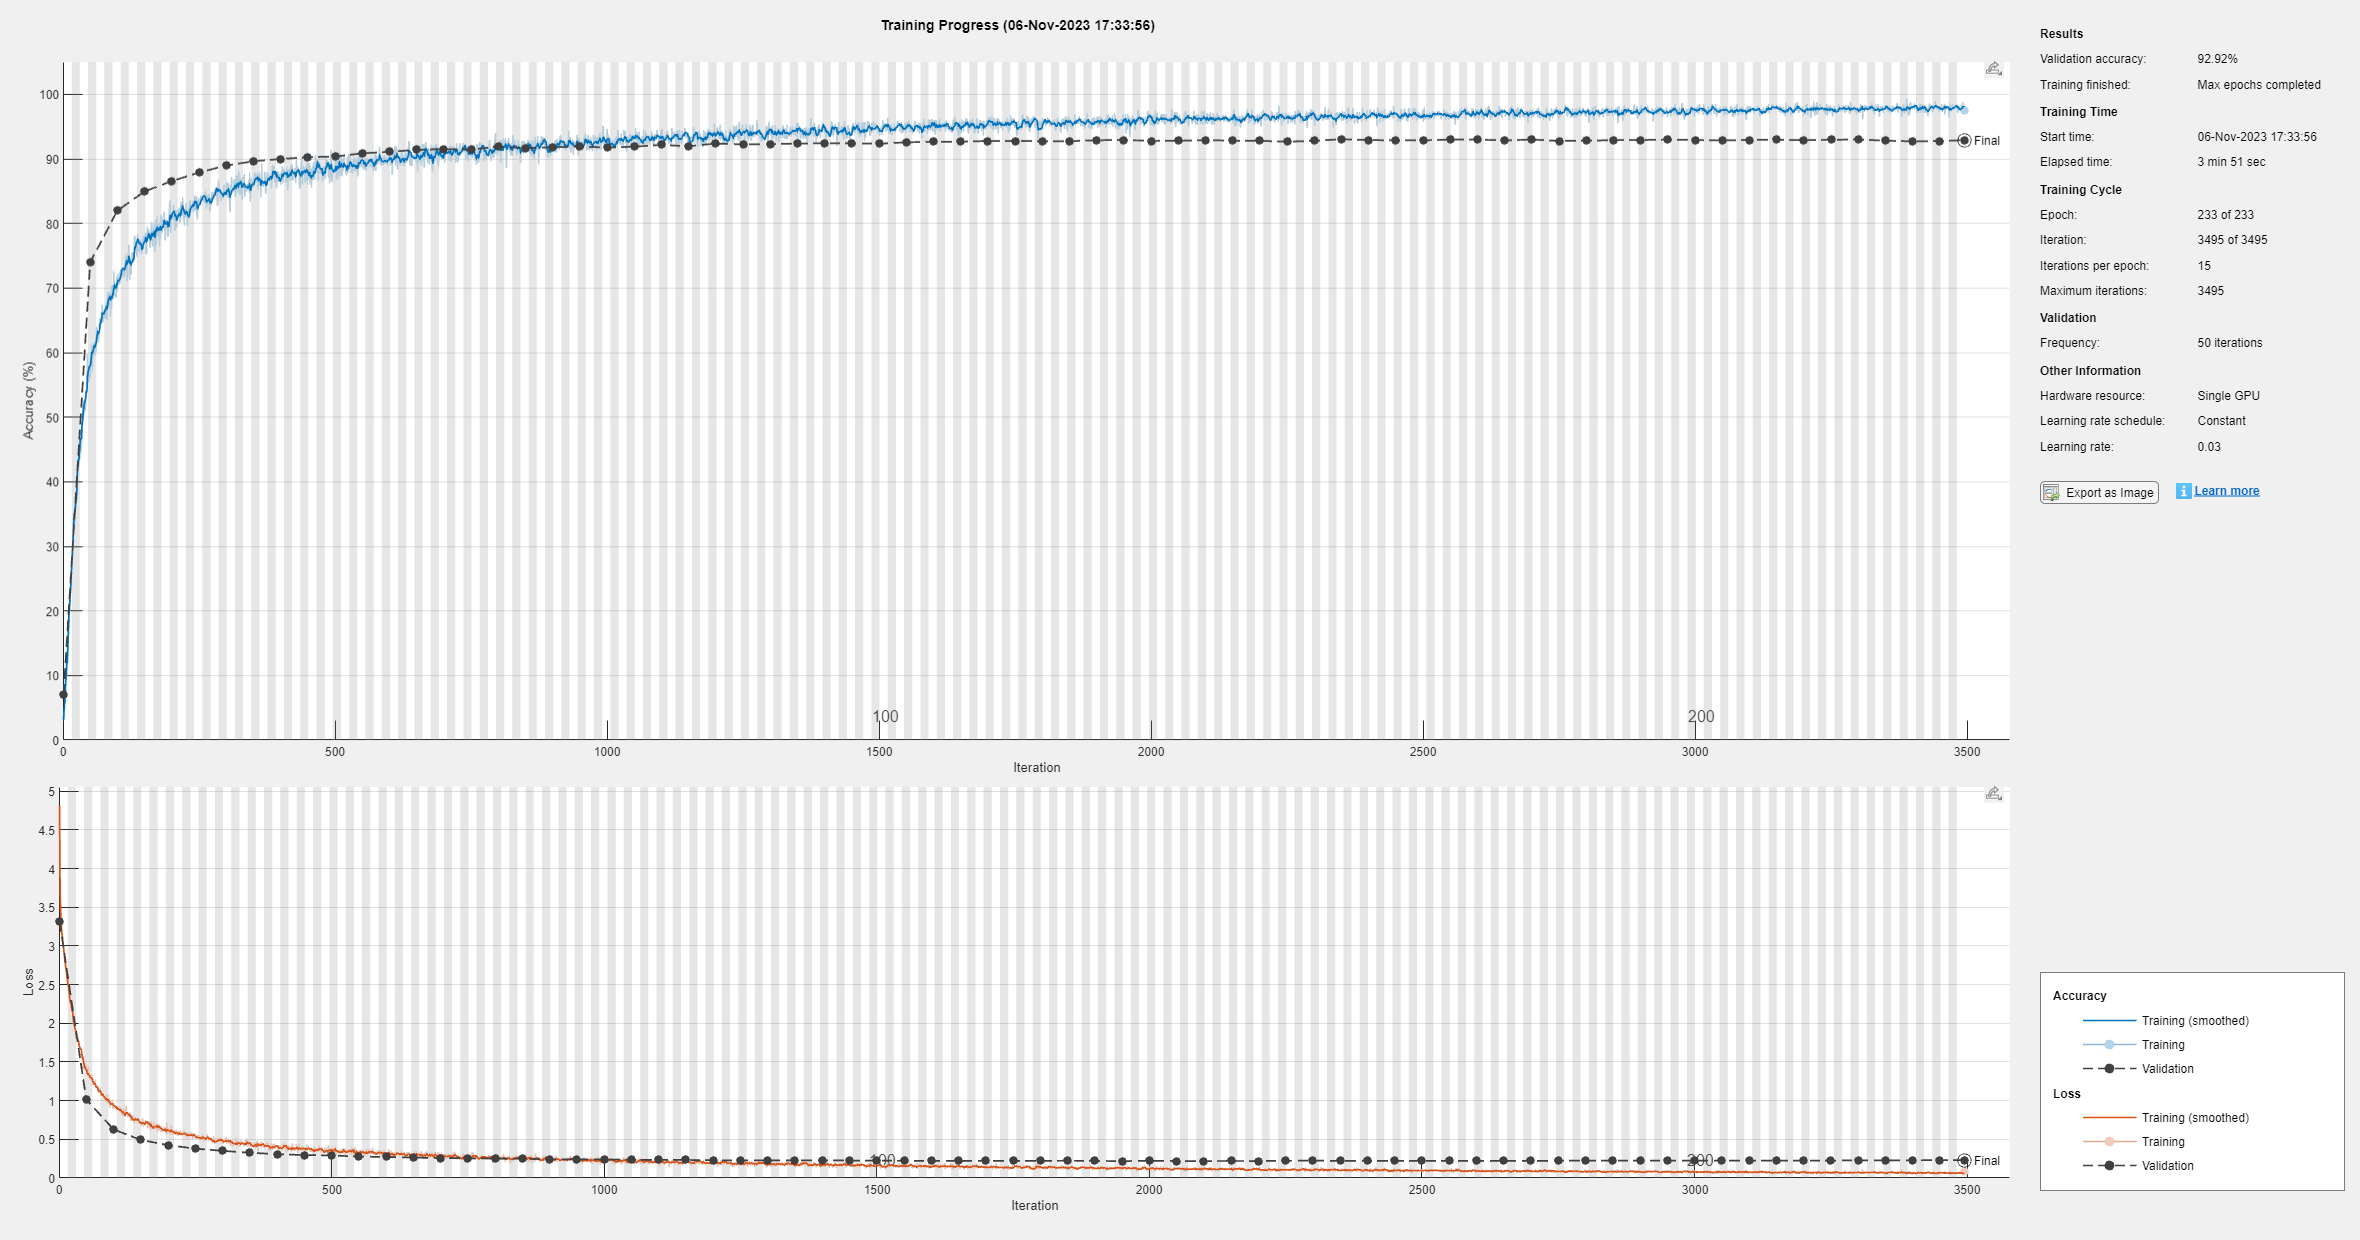

options = trainingOptions('sgdm', ...
    'MaxEpochs', 233, ...
    'MiniBatchSize', 1024, ...
    'InitialLearnRate', 3e-2, ...
    'Momentum', 0.07, ...
    'Shuffle', 'every-epoch', ...
    'ValidationData', {valImages, valLabels}, ...
    'Verbose', true, ...
    'Plots', 'training-progress');
net = trainNetwork(trainImages, trainLabels, GPTdesignedlayers, options);

|===============================================================================================================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | InitialLearn-|     Momentum | kernelsize_g-| numfilters_g-| poolsize_glo-| stride_global|  drop_global | fullyconnect-|
|      | result |             | runtime     | (observed)  | (estim.)    | Rate         |              | lobal        | lobal        | bal          |              |              | edOutput     |
|===============================================================================================================================================================================================|
|    1 | Best   |    0.080245 |      86.216 |    0.080245 |    0.080245 |     0.054473 |      0.31794 |            4 |           82 |            3 |            3 |      0.40086 |          484 |
|    2 | Accept |     0.27133 

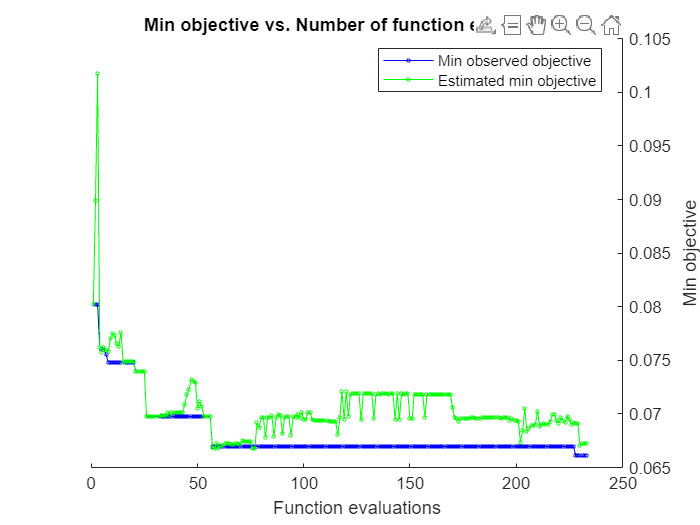


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 233 reached.
Total function evaluations: 233
Total elapsed time: 20091.0501 seconds
Total objective function evaluation time: 19967.6423

Best observed feasible point:
    InitialLearnRate    Momentum    kernelsize_global    numfilters_global    poolsize_global    stride_global    drop_global    fullyconnectedOutput
    ________________    ________    _________________    _________________    _______________    _____________    ___________    ____________________

        0.099657        0.82913             5                   58                   4                 3            0.44012              189        

% Set Hyperparameter Ranges
vars = [
    optimizableVariable('InitialLearnRate', [3e-5, 1e-1], 'Transform', 'log');
    optimizableVariable('Momentum', [0.03, 1]);
    optimizableVariable('kernelsize_global', [2, 7],'Type','integer');
    optimizableVariable('numfilters_global', [16, 128],'Type','integer');
    optimizableVariable('poolsize_global', [2, 4],'Type','integer');
    optimizableVariable('stride_global', [1, 3],'Type','integer');
    optimizableVariable('drop_global', [0.34, 0.91]);
    optimizableVariable('fullyconnectedOutput', [128, 512],'Type','integer');
];

% Run Bayesian Optimization
results = bayesopt(@(params) trainModelWithParameters(params, trainImages, trainLabels, valImages, valLabels, layers), vars, ...
    'MaxObjectiveEvaluations', 233, ...
    'IsObjectiveDeterministic', false, ...
    'AcquisitionFunctionName', 'probability-of-improvement');

% Train the final Network using optimal hyperparameters
optimalParameters = results.XAtMinEstimatedObjective;
overfitParams = results.XAtMinObjective;

% Define the layers of the network
layers = [
    imageInputLayer([28 28 1], 'Name', 'input')
    
    convolution2dLayer(optimalParameters.kernelsize_global, optimalParameters.numfilters_global, 'Padding', 'same', 'Name', 'conv_1')
    reluLayer('Name', 'relu_1')
    dropoutLayer(optimalParameters.drop_global, 'Name', 'dropout1')
    maxPooling2dLayer(optimalParameters.poolsize_global, 'Stride', optimalParameters.stride_global * 2, 'Name', 'maxpool_1')
    
    convolution2dLayer(round(optimalParameters.kernelsize_global/2), round(optimalParameters.numfilters_global / 2), 'Padding', 'same', 'Name', 'conv_2')
    reluLayer('Name', 'relu_2')
    dropoutLayer(optimalParameters.drop_global, 'Name', 'dropout2')
    maxPooling2dLayer(round(optimalParameters.poolsize_global/2), 'Stride', round(optimalParameters.stride_global), 'Name', 'maxpool_2')
    
    fullyConnectedLayer(optimalParameters.fullyconnectedOutput, 'Name', 'fc_1')
    reluLayer('Name', 'relu_3')
    dropoutLayer(optimalParameters.drop_global*0.8, 'Name', 'dropout3')
    
    fullyConnectedLayer(26, 'Name', 'fc_2')
    softmaxLayer('Name', 'softmax')
    classificationLayer('Name', 'classification')
];


overfit_layers = [
    imageInputLayer([28 28 1], 'Name', 'input')
    
    convolution2dLayer(overfitParams.kernelsize_global, overfitParams.numfilters_global, 'Padding', 'same', 'Name', 'conv_1')
    reluLayer('Name', 'relu_1')
    dropoutLayer(overfitParams.drop_global, 'Name', 'dropout1')
    maxPooling2dLayer(overfitParams.poolsize_global, 'Stride', overfitParams.stride_global * 2, 'Name', 'maxpool_1')
    
    convolution2dLayer(round(overfitParams.kernelsize_global/2), round(overfitParams.numfilters_global/2), 'Padding', 'same', 'Name', 'conv_2')
    reluLayer('Name', 'relu_2')
    dropoutLayer(overfitParams.drop_global, 'Name', 'dropout2')
    maxPooling2dLayer(round(overfitParams.poolsize_global/2), 'Stride', round(overfitParams.stride_global/2), 'Name', 'maxpool_2')
    
    fullyConnectedLayer(overfitParams.fullyconnectedOutput, 'Name', 'fc_1')
    reluLayer('Name', 'relu_3')
    dropoutLayer(overfitParams.drop_global*0.8, 'Name', 'dropout3')
    
    fullyConnectedLayer(26, 'Name', 'fc_2')
    softmaxLayer('Name', 'softmax')
    classificationLayer('Name', 'classification')
];

% Display the network architecture
disp(layers);

  15×1 Layer array with layers:

     1   'input'            Image Input             28×28×1 images with 'zerocenter' normalization
     2   'conv_1'           2-D Convolution         114 4×4 convolutions with stride [1  1] and padding 'same'
     3   'relu_1'           ReLU                    ReLU
     4   'dropout1'         Dropout                 37% dropout
     5   'maxpool_1'        2-D Max Pooling         2×2 max pooling with stride [4  4] and padding [0  0  0  0]
     6   'conv_2'           2-D Convolution         57 2×2 convolutions with stride [1  1] and padding 'same'
     7   'relu_2'           ReLU                    ReLU
     8   'dropout2'         Dropout                 37% dropout
     9   'maxpool_2'        2-D Max Pooling         1×1 max pooling with stride [2  2] and padding [0  0  0  0]
    10   'fc_1'             Fully Connected         380 fully connected layer
    11   'relu_3'         

Training on single GPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:01 |        2.83% |        2.53% |       3.2722 |       3.2624 |          0.0380 |
|       4 |          50 |       00:00:05 |       47.75% |       57.80% |       1.7719 |       1.7157 |          0.0380 |
|       7 |         100 |       00:00:09 |       66.70% |       74.69% |       1.0466 |       1.0163 |          0.0380 |
|      10 |         150 |       00:00:14 |       72.66% |       80.45% |       0.8587 |   

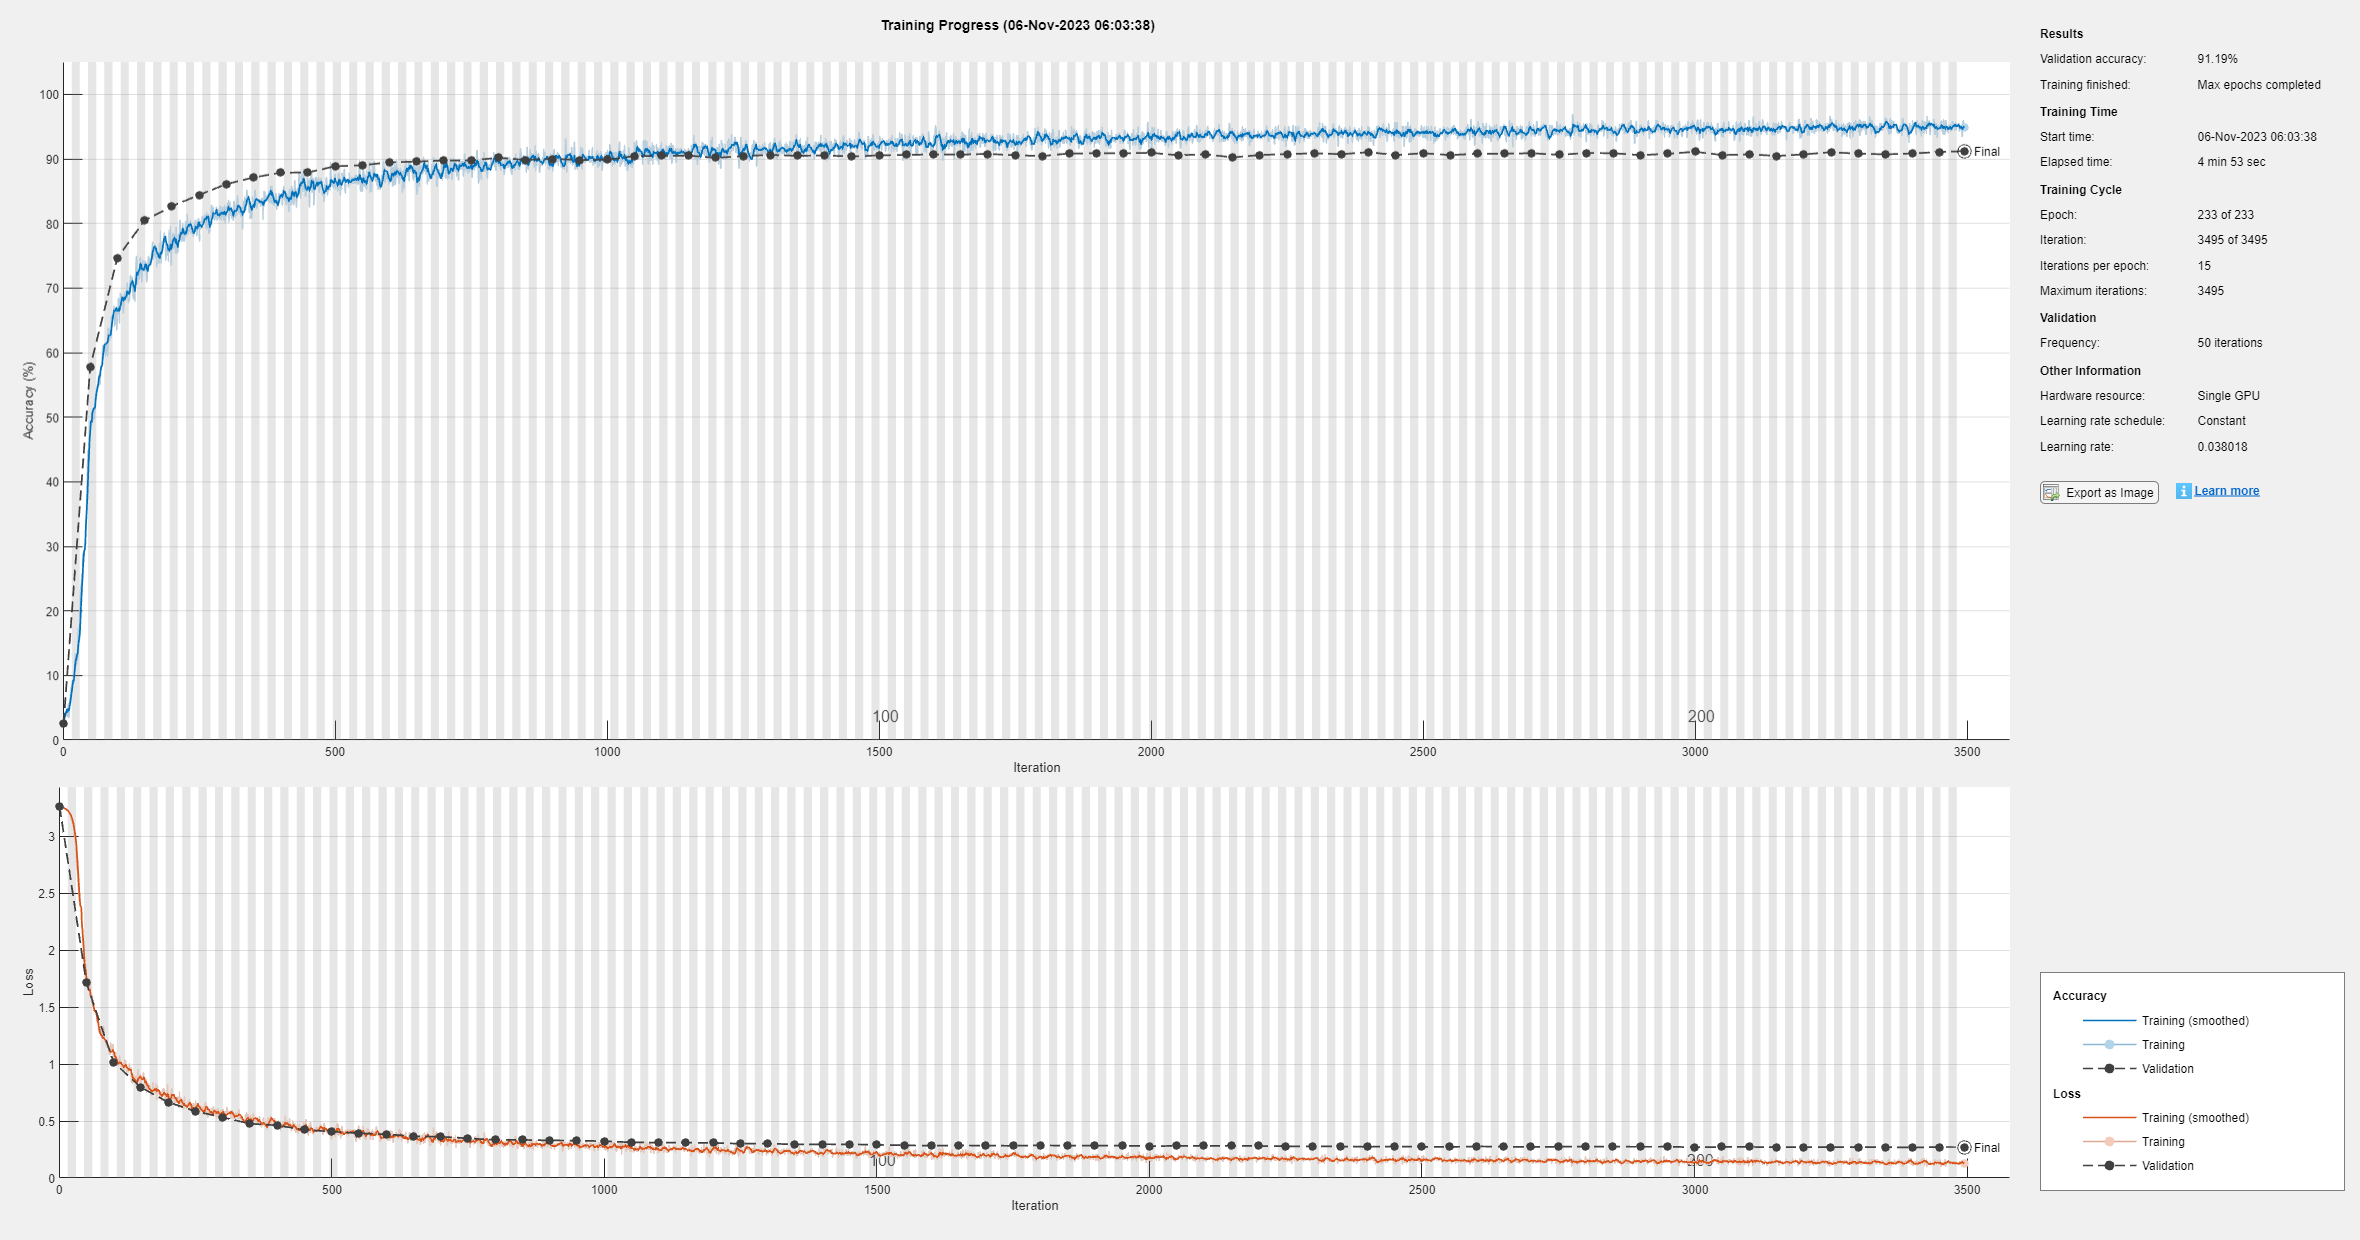

options = trainingOptions('sgdm', ...
    'MaxEpochs', 233, ...
    'MiniBatchSize', 1024, ...
    'InitialLearnRate', optimalParameters.InitialLearnRate, ...
    'Momentum', optimalParameters.Momentum, ...
    'Shuffle', 'every-epoch', ...
    'ValidationData', {valImages, valLabels}, ...
    'Verbose', true, ...
    'Plots', 'training-progress');
net = trainNetwork(trainImages, trainLabels, layers, options);

Training on single GPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:01 |        4.00% |        2.67% |       3.2843 |       3.2589 |          0.0380 |
|       4 |          50 |       00:00:03 |       38.18% |       55.79% |       1.9464 |       2.1559 |          0.0380 |
|       7 |         100 |       00:00:05 |       62.30% |       77.34% |       1.1777 |       1.3051 |          0.0380 |
|      10 |         150 |       00:00:07 |       70.31% |       82.83% |       0.8497 |   

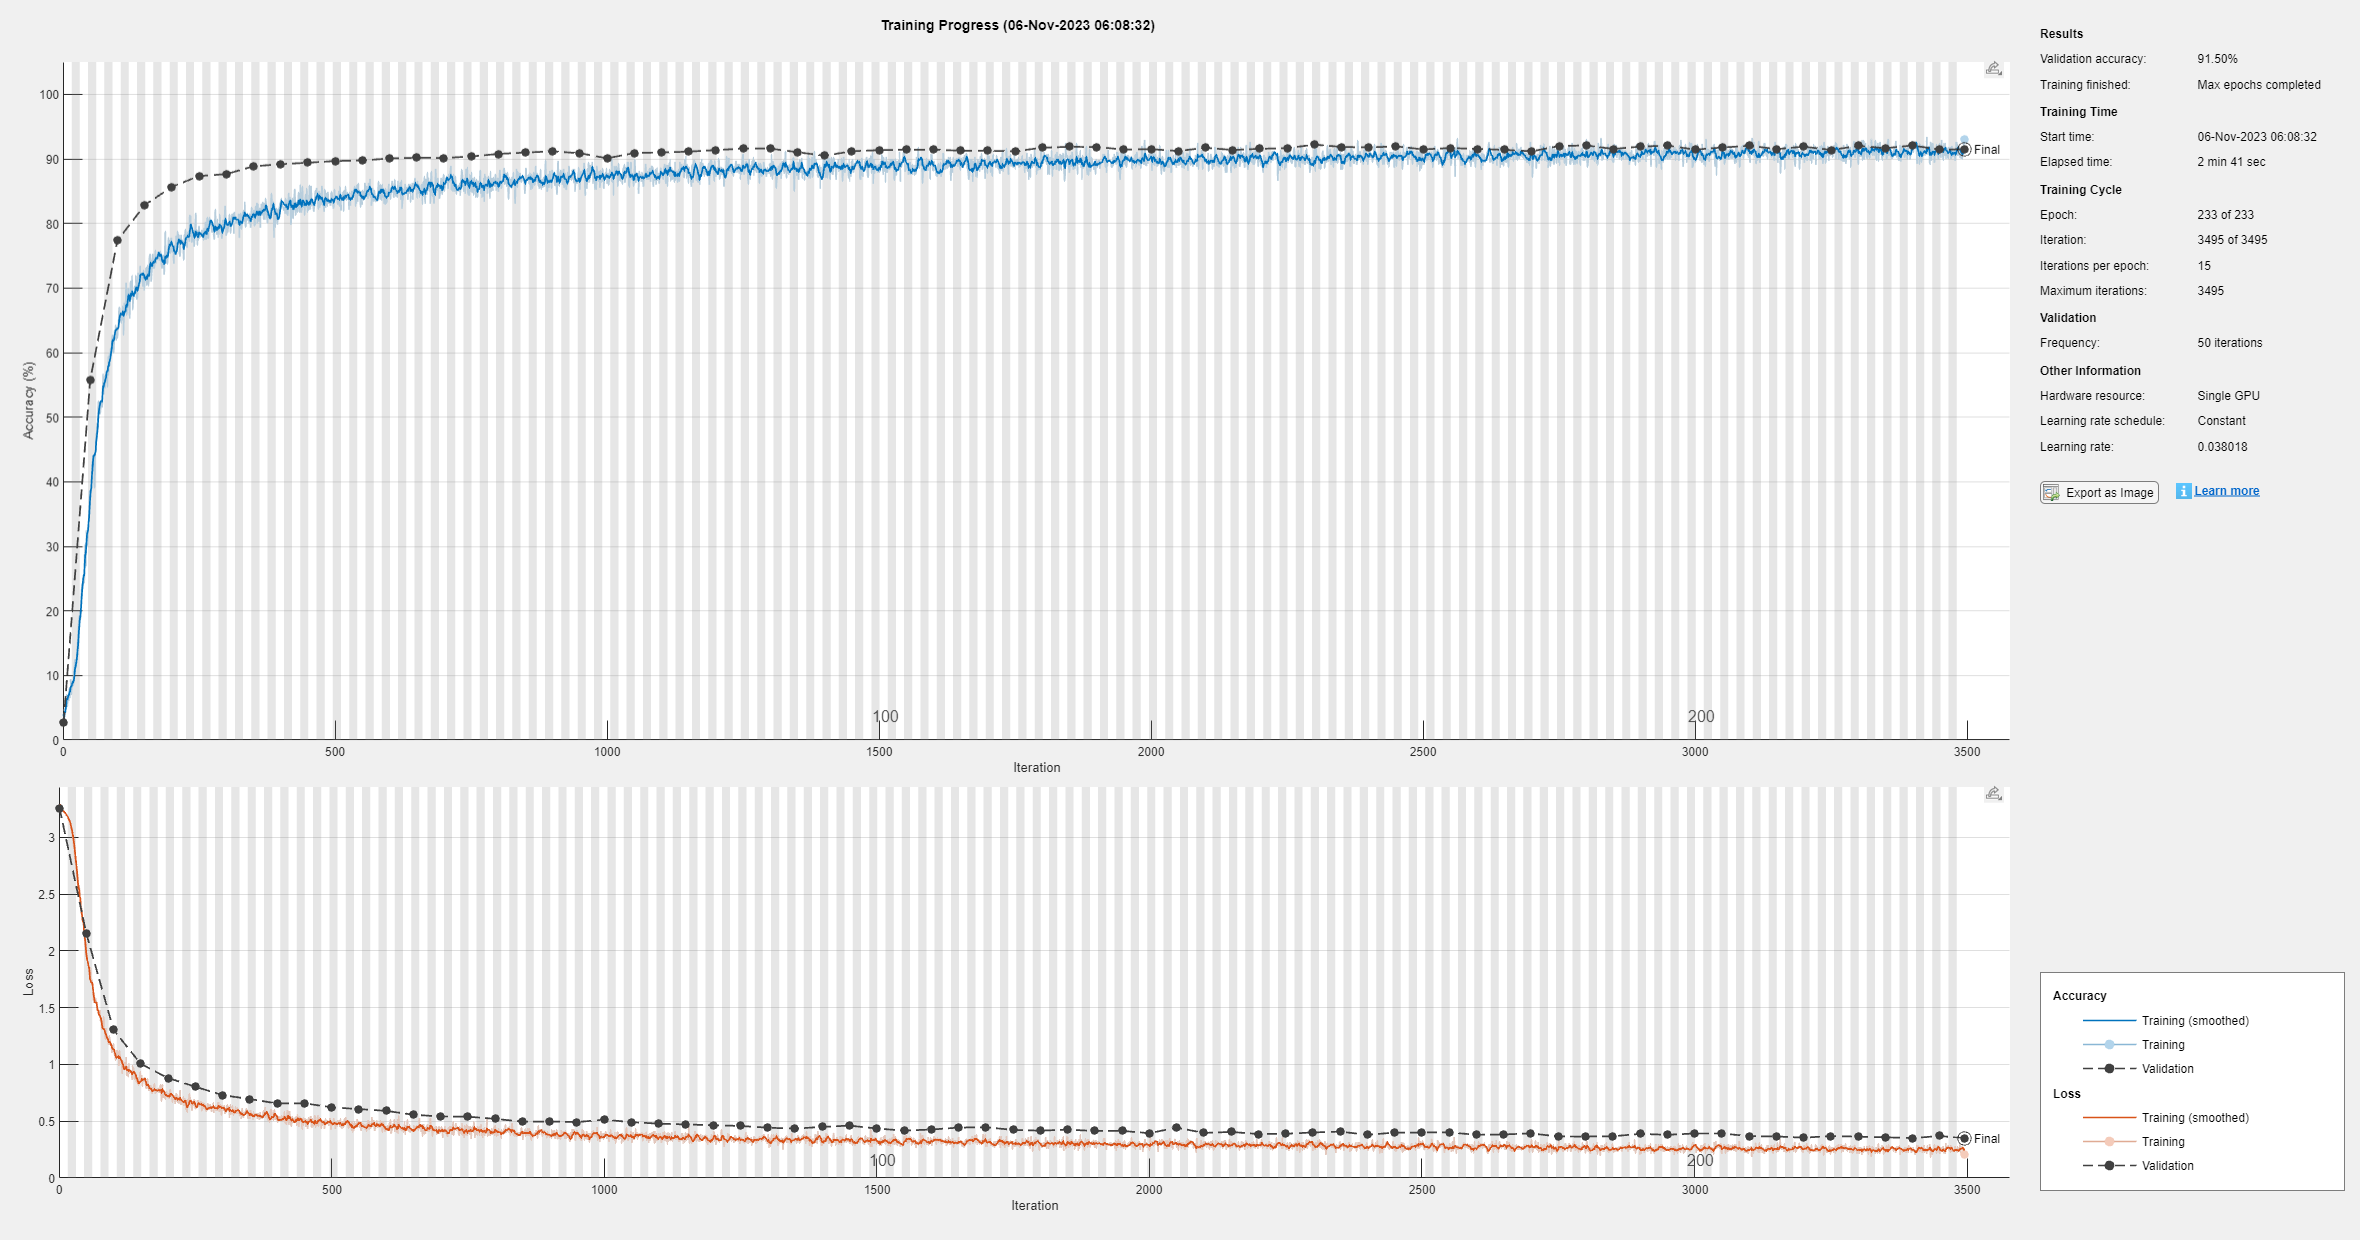

over_net = trainNetwork(trainImages, trainLabels, overfit_layers, options);

Training on single GPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:01 |        2.93% |        4.62% |       3.2632 |       3.2591 |          0.0380 |
|       4 |          50 |       00:00:07 |       26.95% |       52.64% |       2.4884 |       2.0109 |          0.0380 |
|       7 |         100 |       00:00:13 |       53.22% |       70.02% |       1.5587 |       1.2775 |          0.0380 |
|      10 |         150 |       00:00:19 |       60.55% |       78.64% |       1.2895 |   

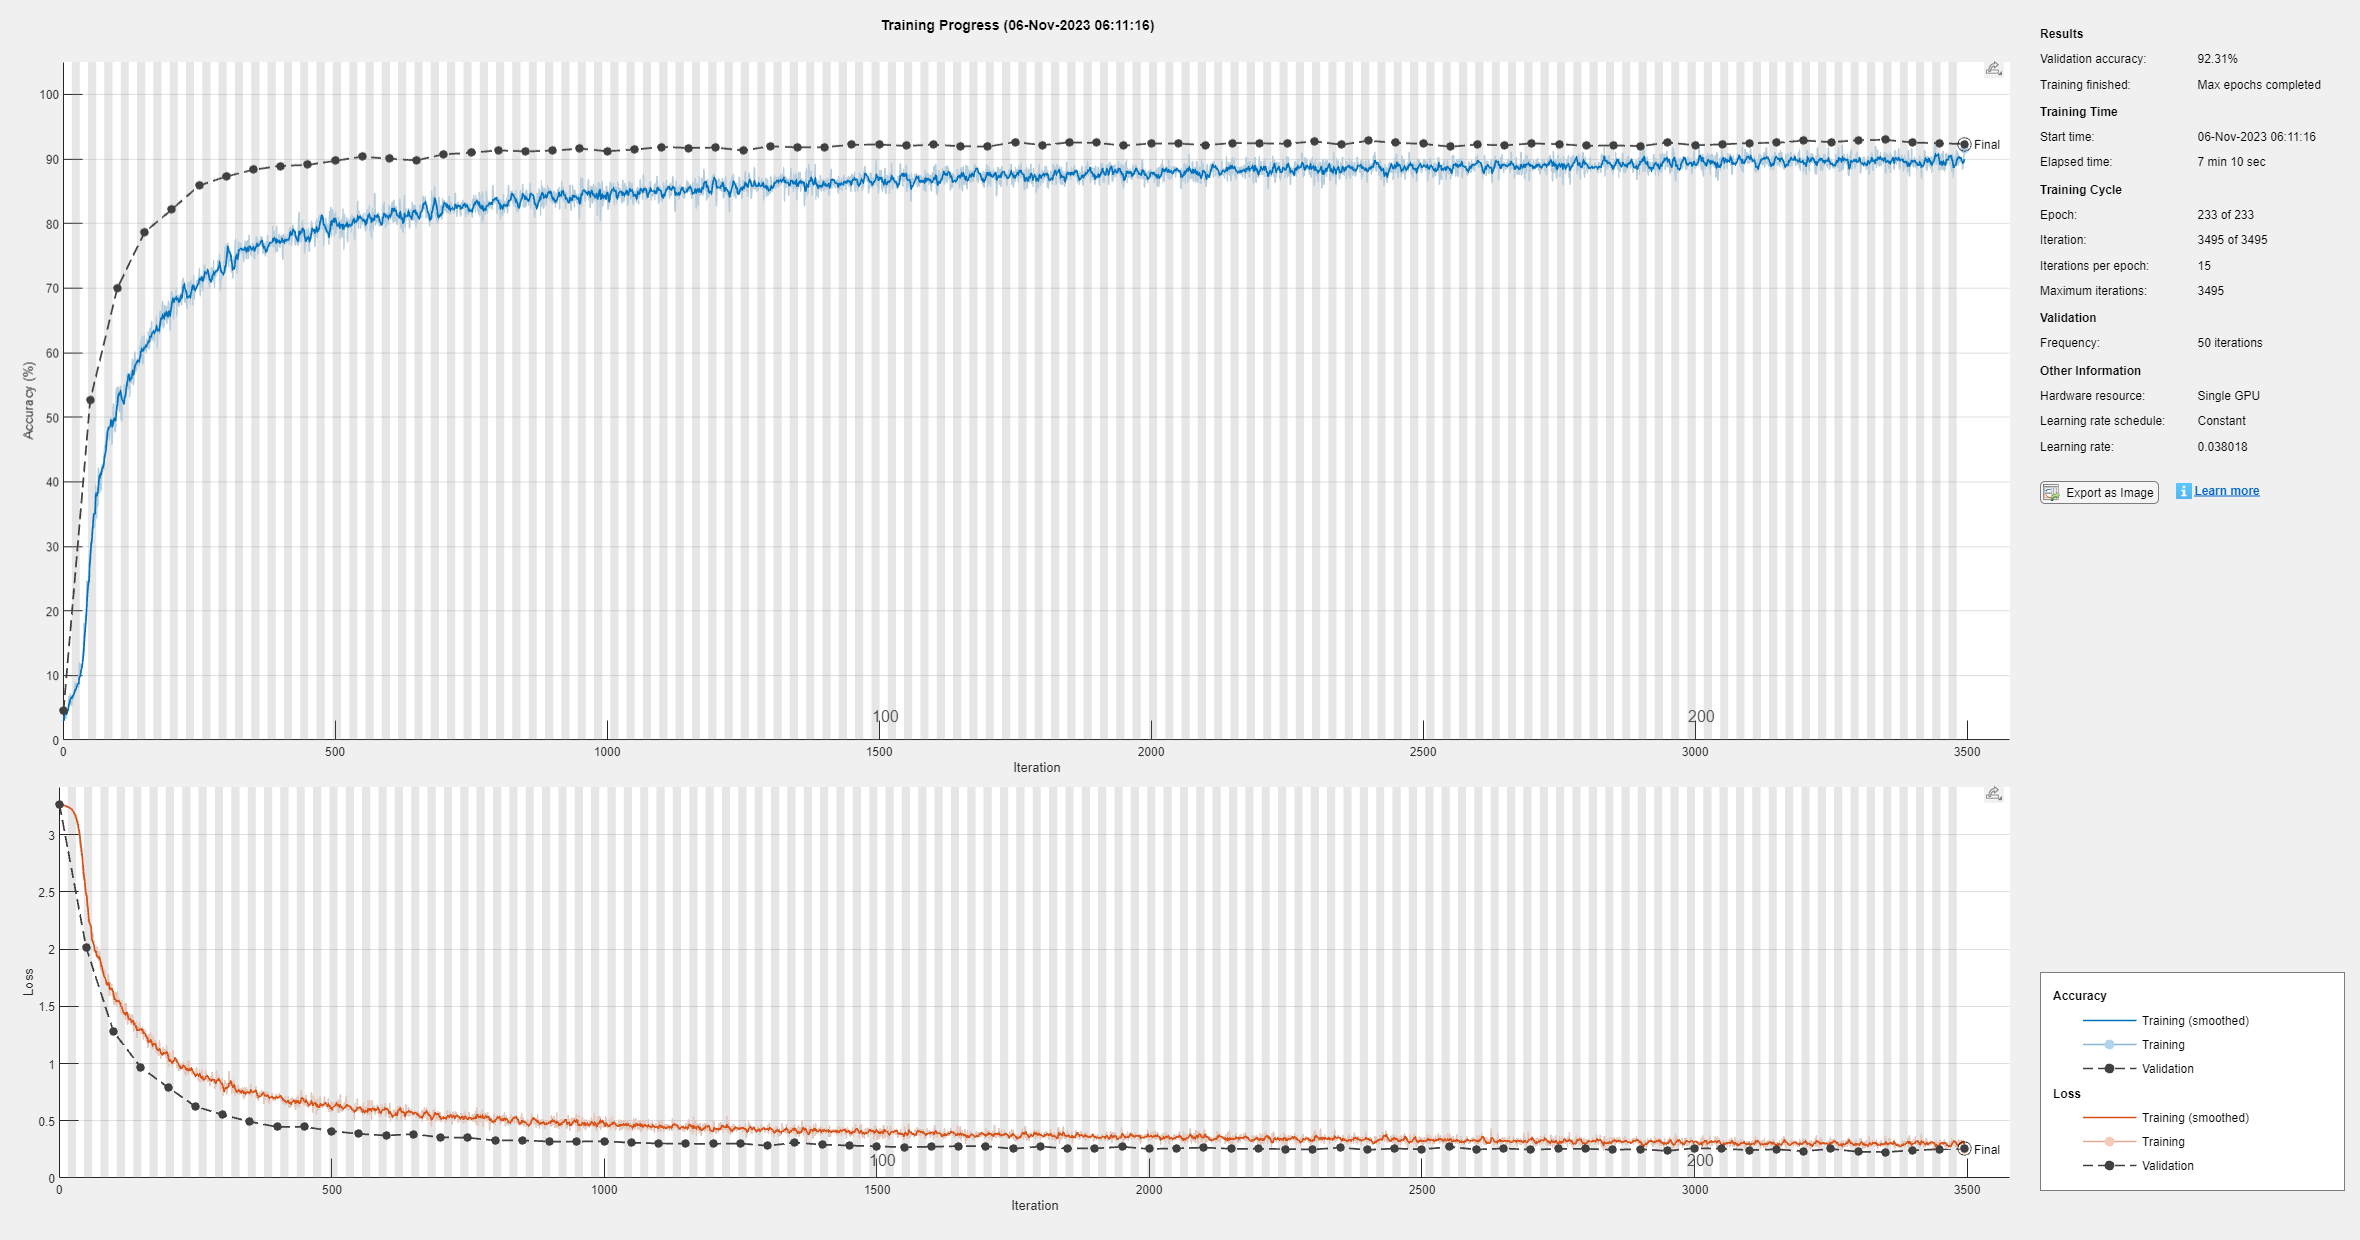

aug_net = trainNetwork(augmentedTrainImages, layers, options);

Training on single GPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:01 |        3.91% |        4.21% |       3.2673 |       3.2575 |          0.0380 |
|       4 |          50 |       00:00:05 |       28.81% |       49.60% |       2.3100 |       2.3992 |          0.0380 |
|       7 |         100 |       00:00:09 |       59.28% |       77.12% |       1.3107 |       1.3031 |          0.0380 |
|      10 |         150 |       00:00:14 |       67.09% |       80.24% |       1.0002 |   

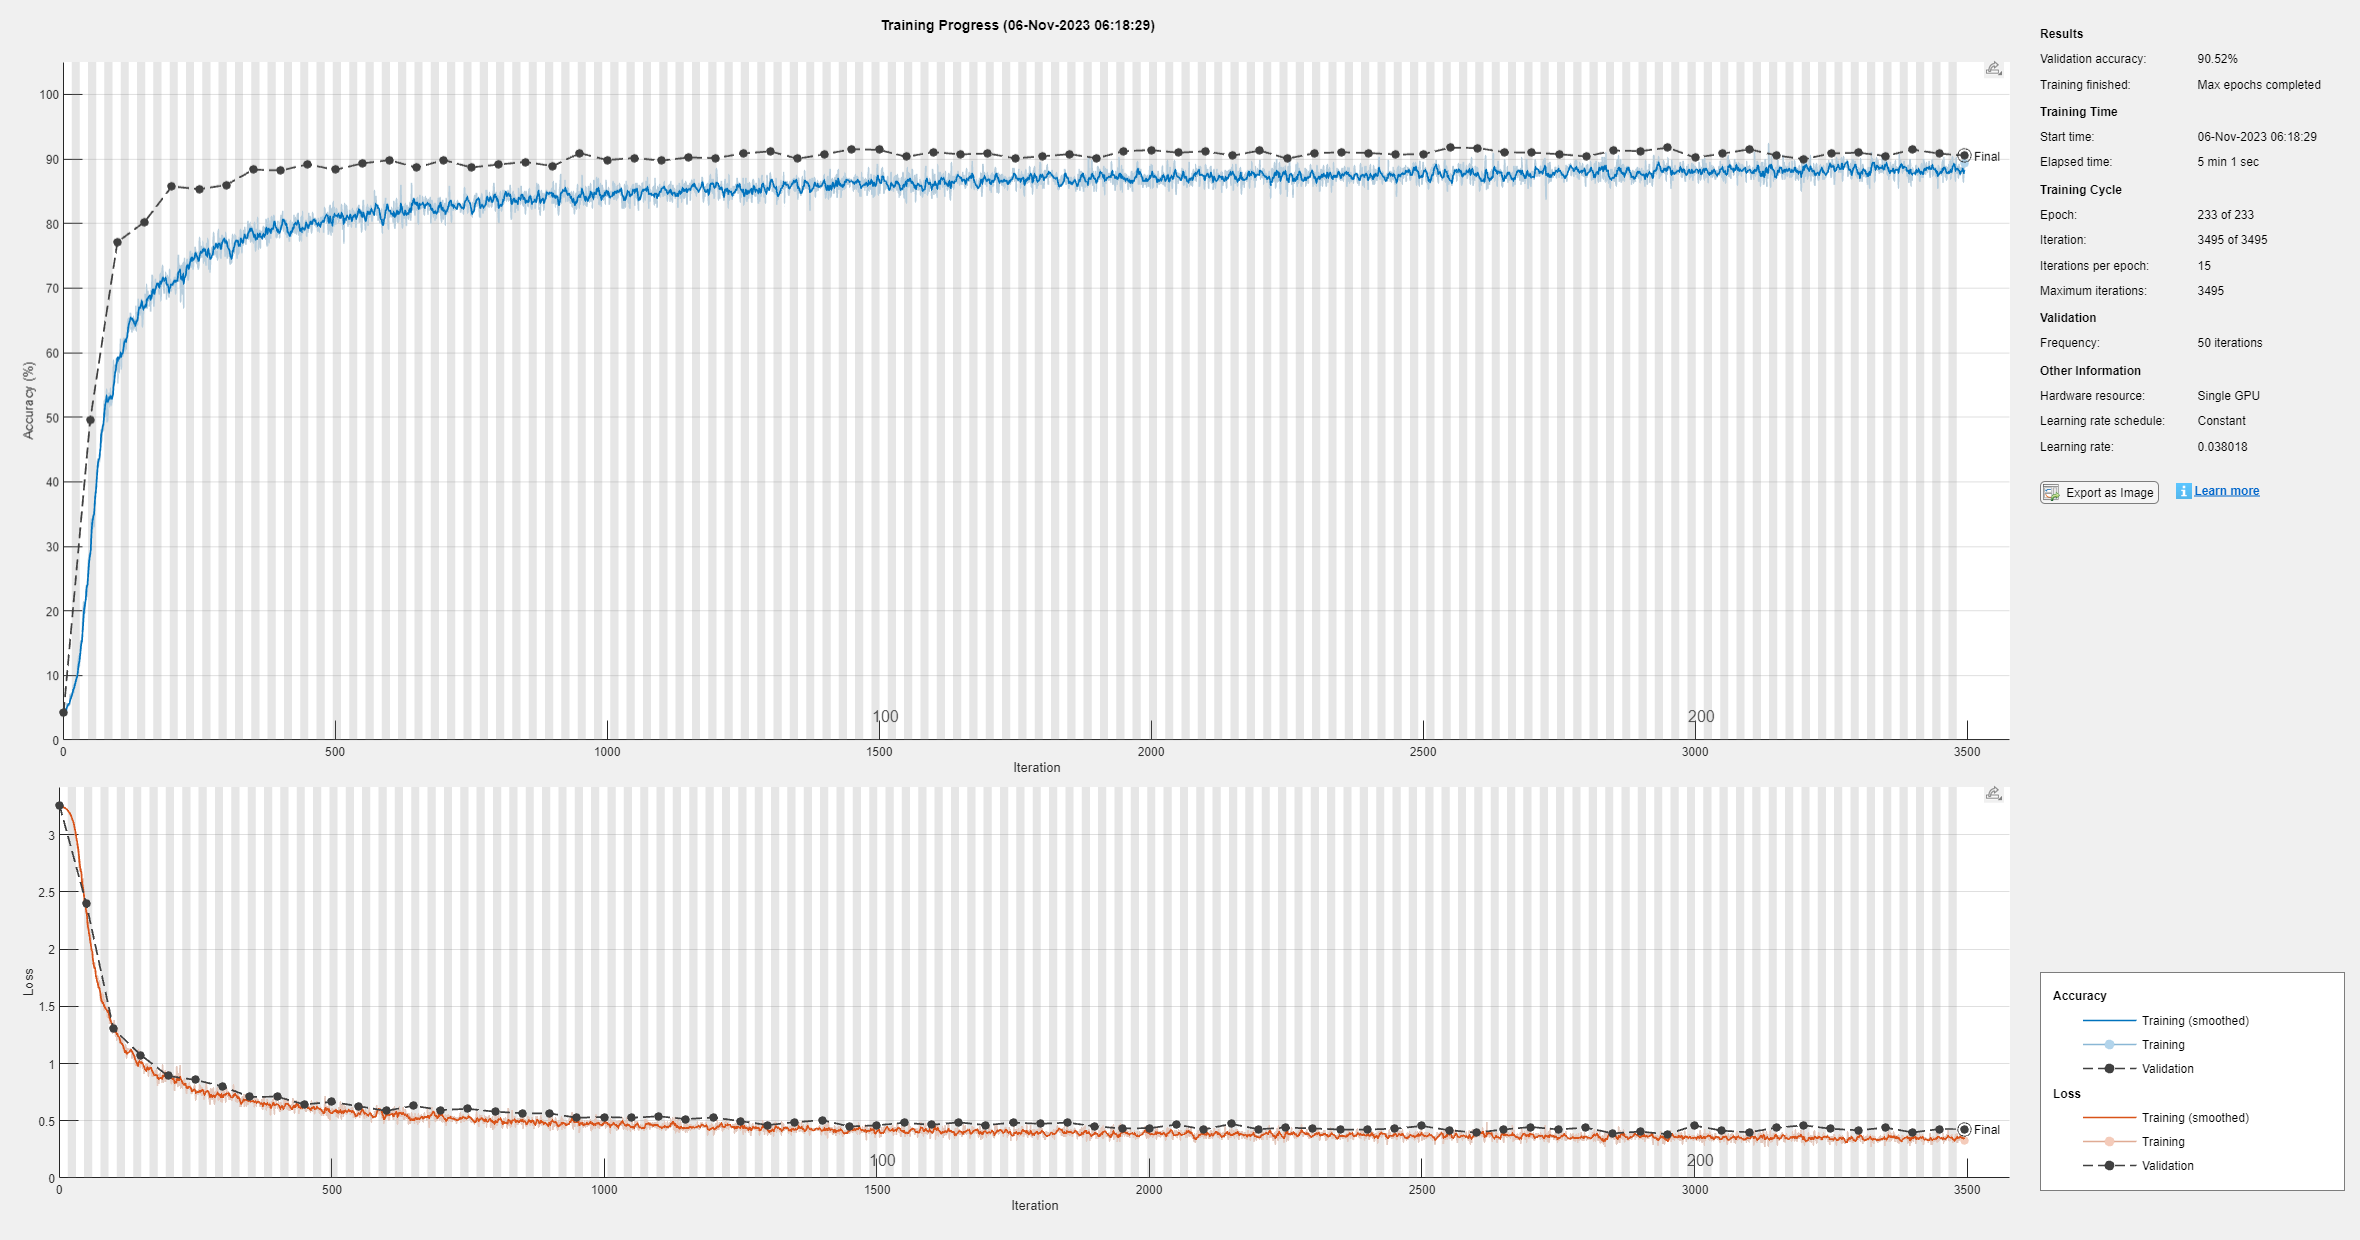

over_aug_net =  trainNetwork(augmentedTrainImages, overfit_layers, options);


% Evaluation
predictedLabels = classify(net, testImages);
aug_predictedLabels = classify(aug_net, testImages);
accuracy = sum(predictedLabels == testLabels) / numel(testLabels);
aug_accuracy = sum(aug_predictedLabels == testLabels) / numel(testLabels);
loss = 1 - accuracy; % Classification loss
aug_loss = 1 - aug_accuracy; % Classification loss

disp(['Test Accuracy: ', num2str(accuracy)]);

Test Accuracy: 0.90841


disp(['Aug Test Accuracy: ', num2str(aug_accuracy)]);

Aug Test Accuracy: 0.92115


disp(['Classification Loss: ', num2str(loss)]);

Classification Loss: 0.091587


disp(['Classification Loss: ', num2str(aug_loss)]);

Classification Loss: 0.078846


% Display optimal hyperparameters
disp('Optimal Hyperparameters:');

Optimal Hyperparameters:


disp(results.XAtMinEstimatedObjective);

    InitialLearnRate    Momentum    kernelsize_global    numfilters_global    poolsize_global    stride_global    drop_global    fullyconnectedOutput
    ________________    ________    _________________    _________________    _______________    _____________    ___________    ____________________

        0.038018        0.93382             4                   114                  2                 2            0.37244              380         



figure; % Open a new figure show samples
num_samples_to_show = 12

num_samples_to_show = 12

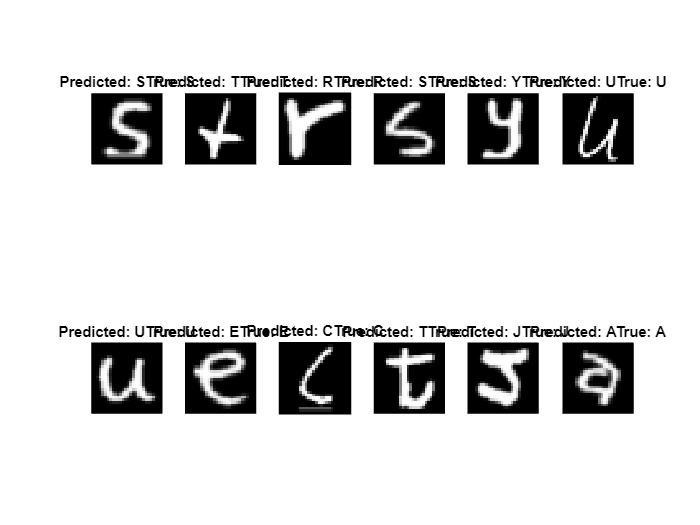

for i = 1:num_samples_to_show
    % Reshape the image from [28, 28, 1] to [28, 28] for visualization
    img = reshape(testImages(:, :, :, i), [28, 28]);
    
    % Display the image in a subplot
    subplot(2, num_samples_to_show/2, i);
    imshow(img, []);
    titleStr = ['Predicted: ', char(dataset.key(predictedLabels(i))), ...
                'True: ', char(dataset.key(testLabels(i)))];
    title(titleStr);
end

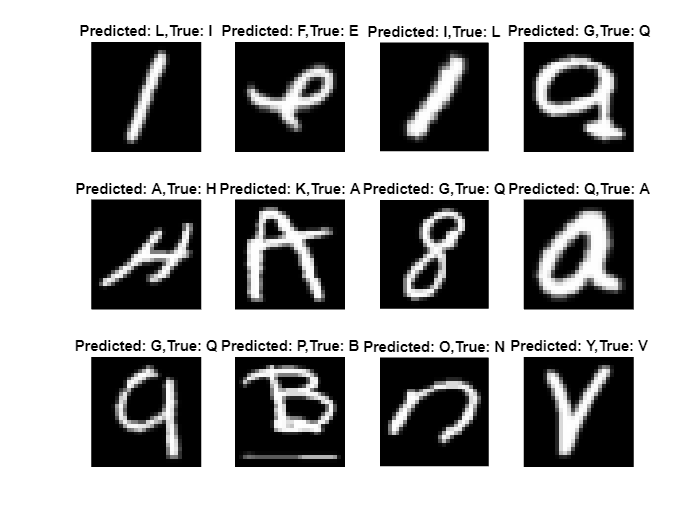

wrongIndices = showWronglyClassifiedSamples(testImages, testLabels, predictedLabels, dataset, num_samples_to_show);

function [trainData, valData, testData] = splitDataset(dataset, trainRatio, valRatio)
    % This function splits the dataset into training, validation, and test sets
    % based on the provided ratios.
    
    % Check if ratios sum to 1
    if trainRatio + valRatio > 1
        error('The sum of trainRatio and valRatio should be <= 1');
    end
    
    % Shuffle the dataset
    totalSamples = size(dataset.images, 1);
    perm = randperm(totalSamples);
    shuffledImages = dataset.images(perm, :);
    shuffledLabels = dataset.labels(perm, :);
    
    % Compute split indices
    trainCount = round(totalSamples * trainRatio);
    valCount = round(totalSamples * valRatio);
    % The remaining samples will be for testing
    testCount = totalSamples - trainCount - valCount;
    
    % Split the dataset
    trainData.images = shuffledImages(1:trainCount, :);
    trainData.labels = shuffledLabels(1:trainCount, :);
    
    valData.images = shuffledImages(trainCount+1:trainCount+valCount, :);
    valData.labels = shuffledLabels(trainCount+1:trainCount+valCount, :);
    
    testData.images = shuffledImages(trainCount+valCount+1:end, :);
    testData.labels = shuffledLabels(trainCount+valCount+1:end, :);
end

function validationLoss = trainModelWithParameters(params, trainImages, trainLabels, valImages, valLabels, layers)
    options = trainingOptions('sgdm', ...
        'MaxEpochs', 89, ...
        'MiniBatchSize', 512, ...
        'InitialLearnRate', params.InitialLearnRate, ...
        'Momentum', params.Momentum, ...
        'ValidationData', {valImages, valLabels}, ...
        'Verbose', false, ...
        'Shuffle', 'every-epoch');
    
    net = trainNetwork(trainImages, trainLabels, layers, options);
    predictedLabels = classify(net, valImages);
    accuracy = sum(predictedLabels == valLabels) / numel(valLabels);
    validationLoss = 1 - accuracy; % Return validation loss
end

function wrongIndices = showWronglyClassifiedSamples(testImages, testLabels, predictedLabels, dataset, num_samples_to_show)
    % Get indices of wrongly classified samples
    wrongIndices = find(predictedLabels ~= testLabels);
    
    % If the number of wrong samples is less than num_samples_to_show, show all of them
    num_wrong_samples = length(wrongIndices);
    num_to_show = min(num_samples_to_show, num_wrong_samples);
    
    figure; % Open a new figure
    
    for i = 1:num_to_show
        % Reshape the image from [28, 28, 1] to [28, 28] for visualization
        img = reshape(testImages(:, :, :, wrongIndices(i)), [28, 28]);
        
        % Display the image in a subplot
        subplot(floor(sqrt(num_to_show)), ceil(num_to_show/floor(sqrt(num_to_show))), i);
        imshow(img, []);
        
        % Title with predicted and true labels
        titleStr = ['Predicted: ', char(dataset.key(predictedLabels(wrongIndices(i)))), ...
                    ',True: ', char(dataset.key(testLabels(wrongIndices(i))))]; % Assuming dataset.key returns the character label
        title(titleStr);
    end
end

% Define a function for k-NN that uses L2 distance
function predictions = knn_L2(trainImages, trainLabels, testImages, k)
    numTest = size(testImages, 2);
    predictions = zeros(numTest, 1);
    
    for i = 1:numTest
        distances = sqrt(sum((trainImages - testImages(:,i)).^2, 1));
        [~, sortedIndices] = sort(distances);
        closestLabels = trainLabels(sortedIndices(1:k));
        predictions(i) = mode(closestLabels);
    end
end

% Define a function for k-NN that uses L1 distance
function predictions = knn_L1(trainImages, trainLabels, testImages, k)
    numTest = size(testImages, 2);
    predictions = zeros(numTest, 1);
    
    for i = 1:numTest
        distances = sum(abs(trainImages - testImages(:,i)), 1);
        [~, sortedIndices] = sort(distances);
        closestLabels = trainLabels(sortedIndices(1:k));
        predictions(i) = mode(closestLabels);
    end
end